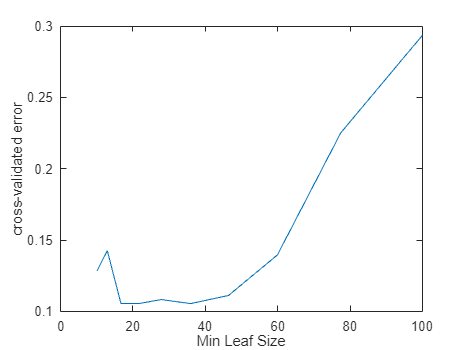

% 选择合适的树深
% 这个例子展示了如何控制决策树的深度，以及如何选择合适的深度。
% 加载电离层数据。
load ionosphere

% 生成一组从 10 到 100 的指数间隔值，表示每个叶节点的最小观察数。
leafs = logspace(1,2,10);

% 为电离层数据创建交叉验证的分类树。指定使用叶子中的最小叶子大小来生长每棵树。
rng('default')
N = numel(leafs);
err = zeros(N,1);
for n=1:N
    t = fitctree(X,Y,'CrossVal','On',...
        'MinLeafSize',leafs(n));
    err(n) = kfoldLoss(t);
end
plot(leafs,err);
xlabel('Min Leaf Size');
ylabel('cross-validated error');

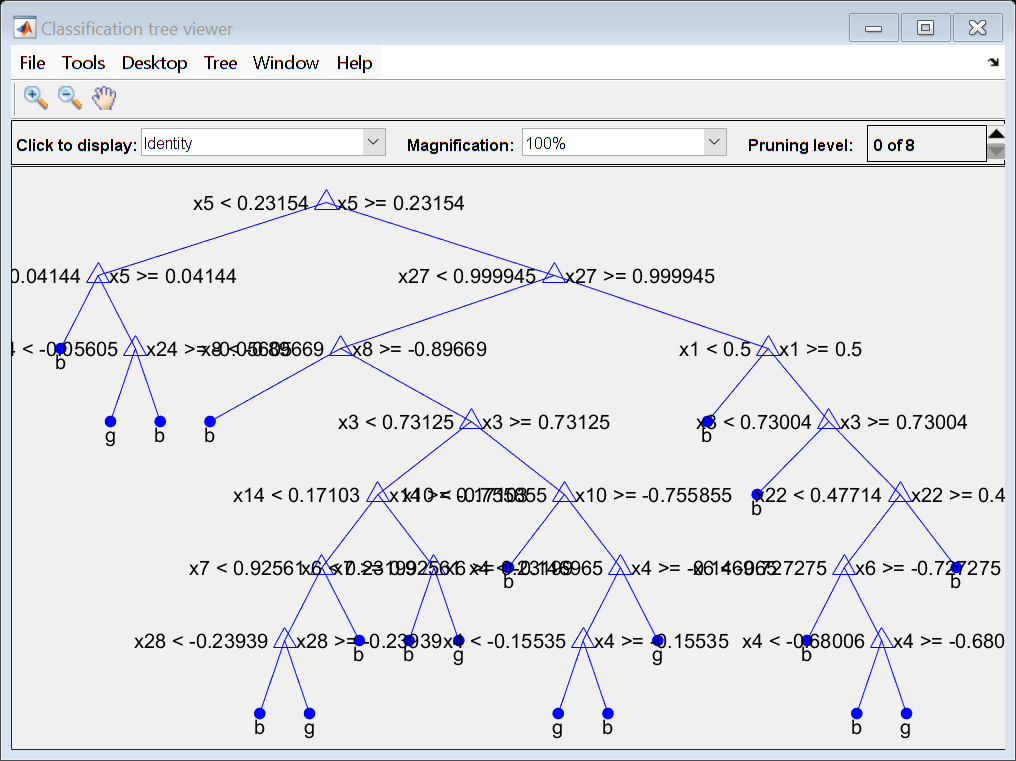

% 最好的叶子大小是每片叶子大约 20 到 50 个观察值之间。


% 将每个叶子至少有 40 个观测值的接近最优树与默认树进行比较，
% 默认树使用每个父节点 10 个观测值和每个叶子节点 1 个观测值。
DefaultTree = fitctree(X,Y);
view(DefaultTree,'Mode','Graph')

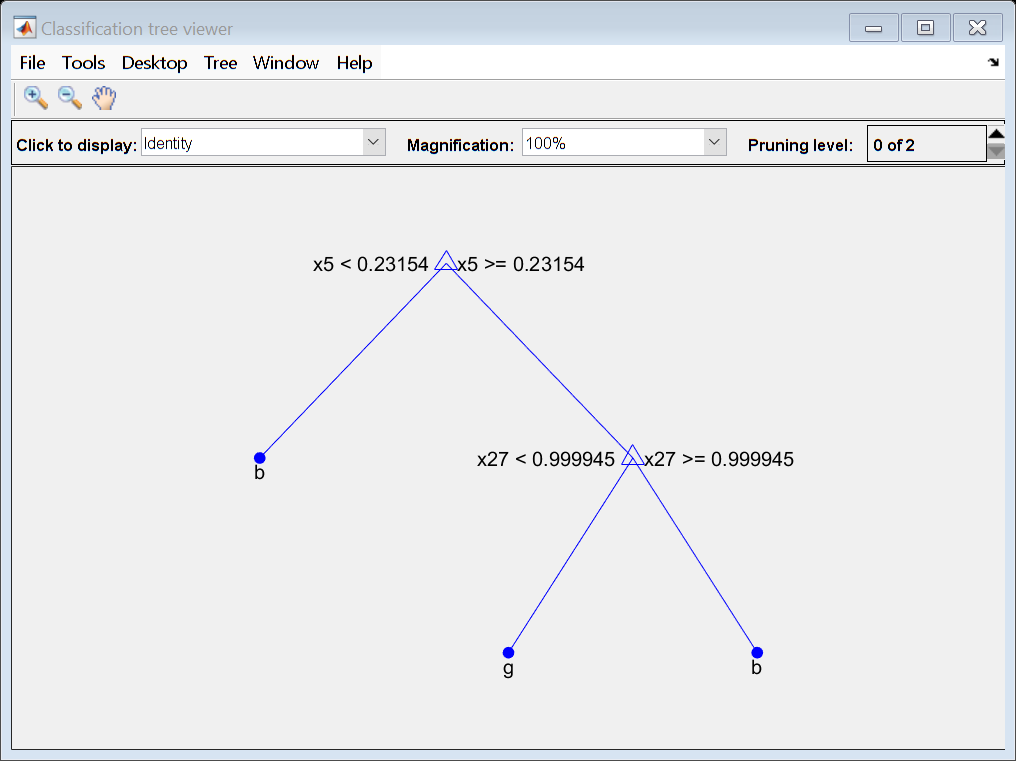


OptimalTree = fitctree(X,Y,'MinLeafSize',40);
view(OptimalTree,'mode','graph')


resubOpt = resubLoss(OptimalTree);
lossOpt = kfoldLoss(crossval(OptimalTree));
resubDefault = resubLoss(DefaultTree);
lossDefault = kfoldLoss(crossval(DefaultTree));
resubOpt,resubDefault,lossOpt,lossDefault

resubOpt = 0.0883

resubDefault = 0.0114

lossOpt = 0.1054

lossDefault = 0.1054

% 接近最优的树要小得多，并给出了更高的再代入误差。
% 然而，它为交叉验证的数据提供了类似的准确性。